# Ejercicio 1 (1,25 puntos). Modelado de sistemas LTI mediante funciones de transferencia.

### G1(s) es una función de transferencia de primer orden con ganancia estática igual a 2 y un polo en s=-5. G2(s) tiene un cero en s=-1 y un polo doble en s=-3. G3(s) es un integrador. Aplicando las reglas básicas del álgebra de bloques, calcula la función de transferencia total en lazo cerrado C(s)/R(s) del sistema de la figura con MATLAB, mostrando el resultado con el numerador y el denominador en forma polinómica: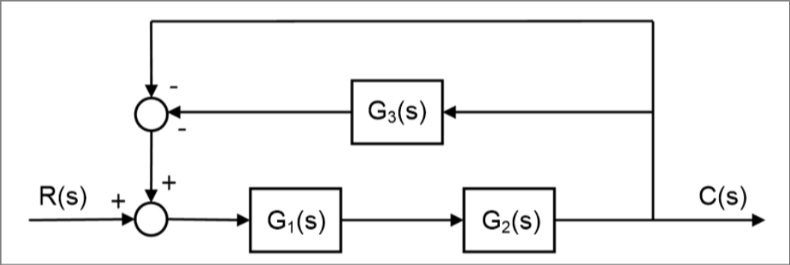

Primero definimos las funciones de transferencia

Como nos los dan en forma factorizada, usamos la función zpk

G1 = zpk([],-5,2)

G1 =
 
    2
  -----
  (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


G2 = zpk(-1,[-3 -3],1) 

G2 =
 
   (s+1)
  -------
  (s+3)^2
 
Continuous-time zero/pole/gain model.
Model Properties


G12s = series(G1,G2)

G12s =
 
     2 (s+1)
  -------------
  (s+3)^2 (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


G3 = -zpk([],0,3)%Integrador -> K/s, donde escogimos k=3

G3 =
 
  -3
  --
  s
 
Continuous-time zero/pole/gain model.
Model Properties


G4 = -1 %Consideramos la parte de arriba como G4,aunque no haya ningun bloque

G4 = -1

G3p = parallel(G3,G4)

G3p =
 
  - (s+3)
  -------
     s
 
Continuous-time zero/pole/gain model.
Model Properties


G1234f = feedback(G12s,G3p,1) %feedback Positivo

G1234f =
 
                 2 s (s+1)
  ---------------------------------------
  (s+0.1249) (s+3) (s^2 + 7.875s + 16.02)
 
Continuous-time zero/pole/gain model.
Model Properties



Cs_Rs = tf(G1234f)

Cs_Rs =
 
            2 s^2 + 2 s
  --------------------------------
  s^4 + 11 s^3 + 41 s^2 + 53 s + 6
 
Continuous-time transfer function.
Model Properties
